Loading the MNIST Datase

[ XTrain , YTrain] = digitTrain4DArrayData ;
[ XTest , YTest] = digitTest4DArrayData ;

figure;

for i = 1:25
subplot(5 ,5 , i )
imshow(XTrain (: ,: ,: , i ));
title (string(YTrain( i )));
drawnow;
end

uiwait(gcf)

Defining the Neural Network

 layers = [
 imageInputLayer([28 28 1])
 convolution2dLayer(3 ,8 , 'Padding' , 'same')
 batchNormalizationLayer
 reluLayer
 maxPooling2dLayer(2 , 'Stride', 2)
 convolution2dLayer(3 ,16 , 'Padding', 'same')
 batchNormalizationLayer
 reluLayer
 fullyConnectedLayer(10)
 softmaxLayer
 classificationLayer
 ];

 % to visualise the architecture

 % lgraph=layerGraph(layers)
 % plot(lgraph)


Training the Network

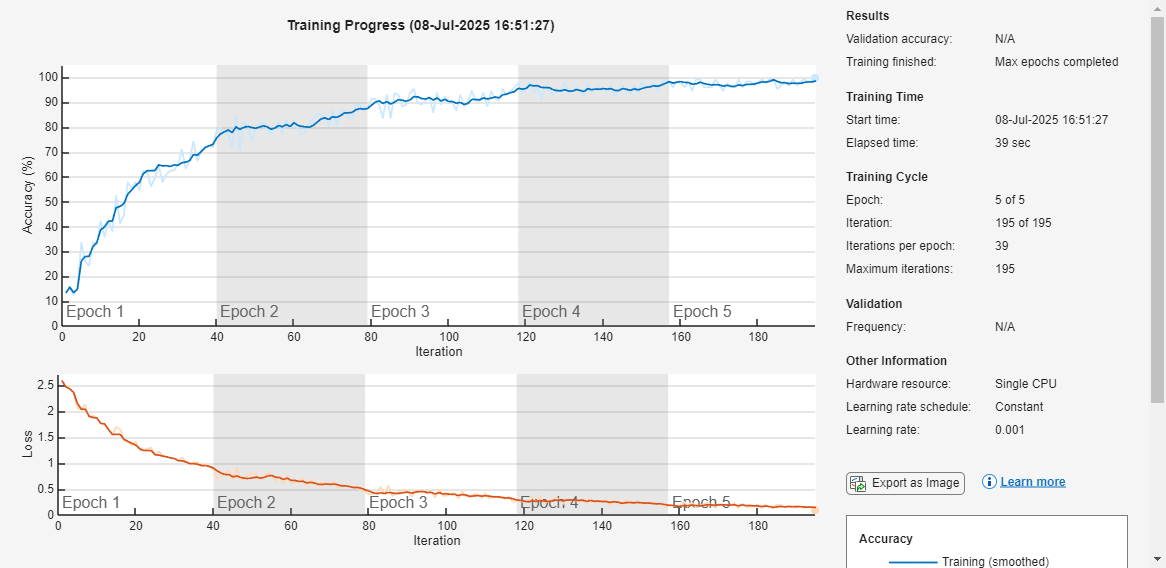

 options = trainingOptions( 'adam' , ...
 'MaxEpochs' ,5 , ...
 'InitialLearnRate' ,1e-3, ...
 'Verbose' , false , ...
 'Plots' , 'training-progress');

 net = trainNetwork(XTrain , YTrain , layers , options );

Testing and Results

YPred = classify(net , XTest);
accuracy = sum(YPred == YTest)/numel(YTest);
fprintf('Test Accuracy: %.2f%%\n' , accuracy * 100);

Test Accuracy: 95.86%
